# **CONTROL DISCRETO**

# FINAL

***Profesor: Ricardo Vecchio***

***Alumna: Trinidad Burs***

***Fecha: 07/07/2021***

***Carga de Datos***

Y  = xlsread('C:\Users\Trini\Documents\UCA\6° Año\Primer Cuatrimestre\Control Discreto\Final\valores_Data_Visualizer.xlsx','B:E');
Yo = xlsread('C:\Users\Trini\Documents\UCA\6° Año\Primer Cuatrimestre\Control Discreto\Final\valores_Data_Visualizer.xlsx','F:I');

***Graficos Data Visualizer***

Se debe pasar el eje "x" a tiempo (no se realiza una simulacion pero una emulacion), actualmente la variable es el numero de muestras.

muestras = max(size(Y));
Tso = 0.006144968142930;
t   = 0:Tso:(Tso*(muestras-1)); %n-1 ya que ya tengo una muestra extra en 0

Se comienza graficando la salida de la planta contra la salida del observador

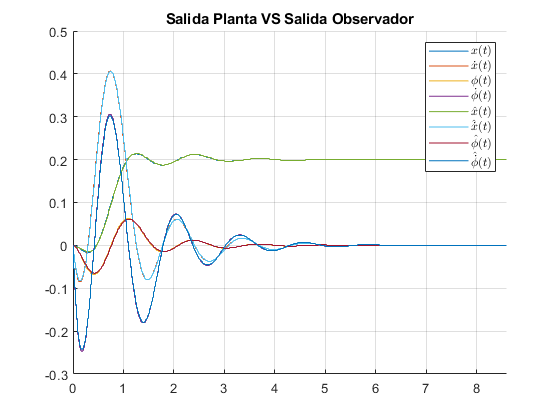

figure(1)
hold on
title('Salida Planta VS Salida Observador')
stairs(t,Y)
stairs(t,Yo)
l=legend({'$x(t)$','$\dot{x}(t)$','$\phi(t)$','$\dot{\phi}(t)$','$\hat{x}(t)$','$\hat{\dot{x}}(t)$','$\hat{\phi}(t)$','$\hat{\dot{\phi}}(t)$'}); 
set(l,'interpreter','latex')
xlim([0 t(end)])
grid on
hold off

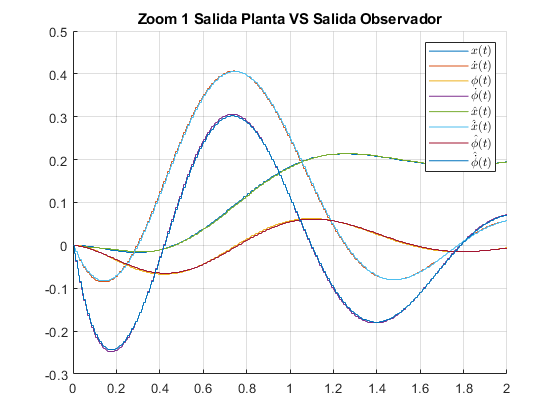


figure(2)
hold on
title('Zoom 1 Salida Planta VS Salida Observador')
stairs(t,Y)
stairs(t,Yo)
l=legend({'$x(t)$','$\dot{x}(t)$','$\phi(t)$','$\dot{\phi}(t)$','$\hat{x}(t)$','$\hat{\dot{x}}(t)$','$\hat{\phi}(t)$','$\hat{\dot{\phi}}(t)$'}); 
set(l,'interpreter','latex')
xlim([0 2])
grid on
hold off

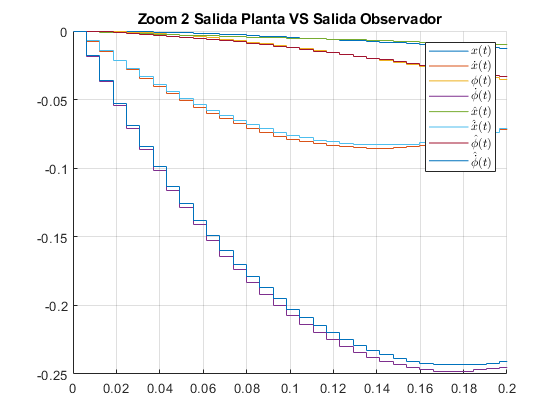


figure(3)
hold on
title('Zoom 2 Salida Planta VS Salida Observador')
stairs(t,Y)
stairs(t,Yo)
l=legend({'$x(t)$','$\dot{x}(t)$','$\phi(t)$','$\dot{\phi}(t)$','$\hat{x}(t)$','$\hat{\dot{x}}(t)$','$\hat{\phi}(t)$','$\hat{\dot{\phi}}(t)$'}); 
set(l,'interpreter','latex')
xlim([0 0.2])
grid on
hold off

***Graficos Data Visualizer VS Simulink***

Para comparar las curvas vistas anteriormente con las generadas en Simulink se utiliza un bloque llamado 'To File' que guarda los datos de la señal indicada en un archivo '.mat'. En la simulacion este bloque esta desactivado. Se proveen los archivo 'output_Y_sim' y 'output_Yo_sim'. Antes de ejecutar el siguiente codigo se los debe cargar en el Workspace.

Se comienza graficando la salida de la planta del PIC contra la salida de la planta del Simulink

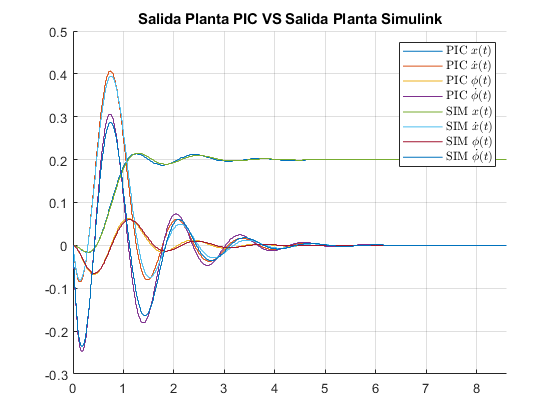

figure(4)
hold on
title('Salida Planta PIC VS Salida Planta Simulink')
stairs(t,Y)
stairs(Y_sim(1,:),Y_sim(2:end,:)')
l=legend({'PIC $x(t)$','PIC $\dot{x}(t)$','PIC $\phi(t)$','PIC $\dot{\phi}(t)$','SIM $x(t)$','SIM $\dot{x}(t)$','SIM $\phi(t)$','SIM $\dot{\phi}(t)$'}); 
set(l,'interpreter','latex')
xlim([0 t(end)])
grid on
hold off

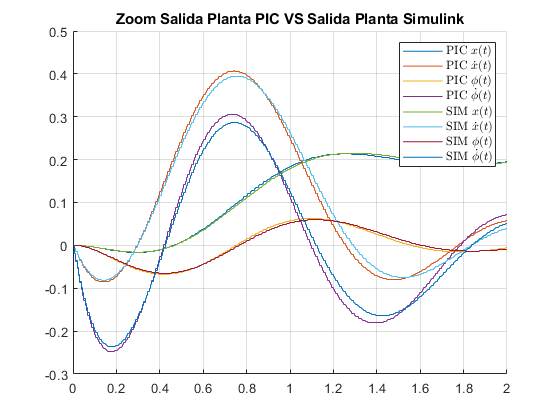


figure(5)
hold on
title('Zoom Salida Planta PIC VS Salida Planta Simulink')
stairs(t,Y)
stairs(Y_sim(1,:),Y_sim(2:end,:)')
l=legend({'PIC $x(t)$','PIC $\dot{x}(t)$','PIC $\phi(t)$','PIC $\dot{\phi}(t)$','SIM $x(t)$','SIM $\dot{x}(t)$','SIM $\phi(t)$','SIM $\dot{\phi}(t)$'}); 
set(l,'interpreter','latex')
xlim([0 2])
grid on
hold off

A continuacion se grafica la salida del observador del PIC contra la salida del observador del Simulink

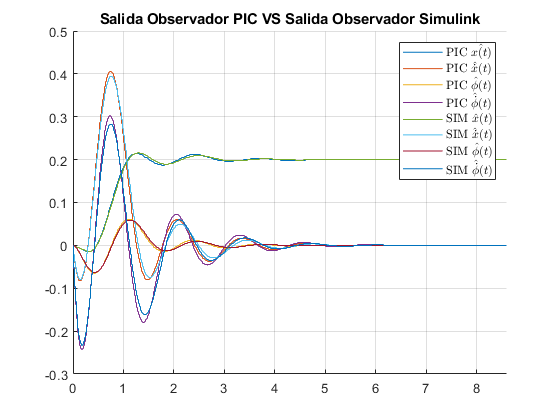

figure(6)
hold on
title('Salida Observador PIC VS Salida Observador Simulink')
stairs(t,Yo)
stairs(Yo_sim(1,:),Yo_sim(2:end,:)')
l=legend({'PIC $\hat{x(t)}$','PIC $\hat{\dot{x}}(t)$','PIC $\hat{\phi}(t)$','PIC $\hat{\dot{\phi}}(t)$','SIM $\hat{x}(t)$','SIM $\hat{\dot{x}}(t)$','SIM $\hat{\phi}(t)$','SIM $\hat{\dot{\phi}}(t)$'}); 
set(l,'interpreter','latex')
xlim([0 t(end)])
grid on
hold off

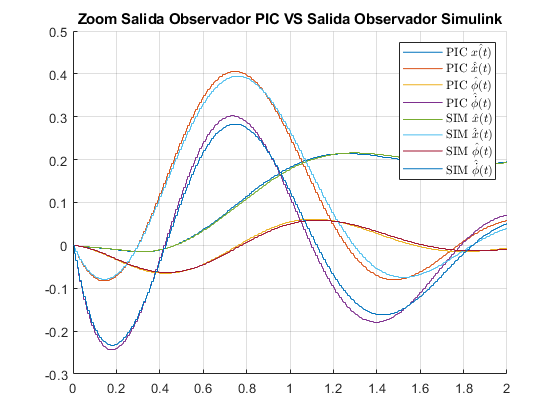


figure(7)
hold on
title('Zoom Salida Observador PIC VS Salida Observador Simulink')
stairs(t,Yo)
stairs(Yo_sim(1,:),Yo_sim(2:end,:)')
l=legend({'PIC $\hat{x(t)}$','PIC $\hat{\dot{x}}(t)$','PIC $\hat{\phi}(t)$','PIC $\hat{\dot{\phi}}(t)$','SIM $\hat{x}(t)$','SIM $\hat{\dot{x}}(t)$','SIM $\hat{\phi}(t)$','SIM $\hat{\dot{\phi}}(t)$'}); 
set(l,'interpreter','latex')
xlim([0 2])
grid on
hold off

***Carga de Double de 24 Bits***

Y_24  = xlsread('C:\Users\Trini\Documents\UCA\6° Año\Primer Cuatrimestre\Control Discreto\Final\valores_Data_Visualizer_24bits.xlsx','B:E');
Yo_24 = xlsread('C:\Users\Trini\Documents\UCA\6° Año\Primer Cuatrimestre\Control Discreto\Final\valores_Data_Visualizer_24bits.xlsx','F:I');

***Graficos Con Double de 24 Bits***

Planta

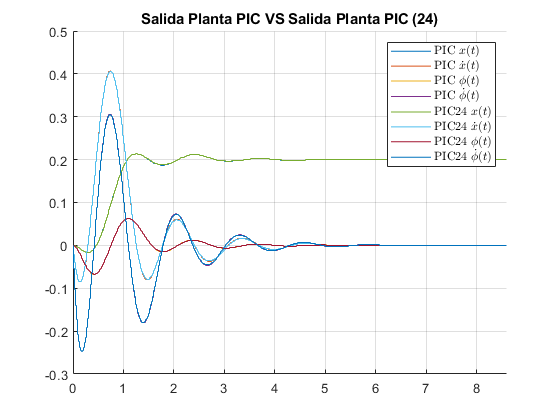

figure(8)
hold on
title('Salida Planta PIC VS Salida Planta PIC (24)')
stairs(t,Y)
stairs(t,Y_24)
l=legend({'PIC $x(t)$','PIC $\dot{x}(t)$','PIC $\phi(t)$','PIC $\dot{\phi}(t)$','PIC24 $x(t)$','PIC24 $\dot{x}(t)$','PIC24 $\phi(t)$','PIC24 $\dot{\phi}(t)$'}); 
set(l,'interpreter','latex')
xlim([0 t(end)])
grid on
hold off

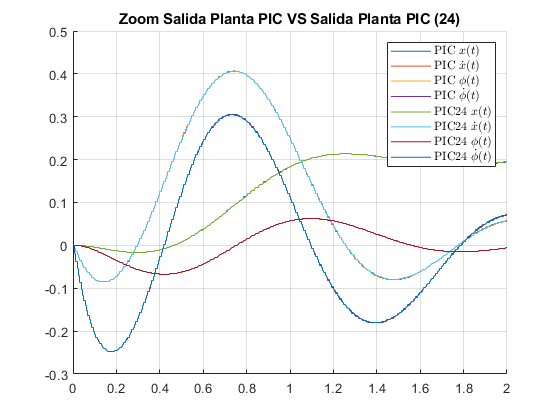


figure(9)
hold on
title('Zoom Salida Planta PIC VS Salida Planta PIC (24)')
stairs(t,Y)
stairs(t,Y_24)
l=legend({'PIC $x(t)$','PIC $\dot{x}(t)$','PIC $\phi(t)$','PIC $\dot{\phi}(t)$','PIC24 $x(t)$','PIC24 $\dot{x}(t)$','PIC24 $\phi(t)$','PIC24 $\dot{\phi}(t)$'}); 
set(l,'interpreter','latex')
xlim([0 2])
grid on
hold off

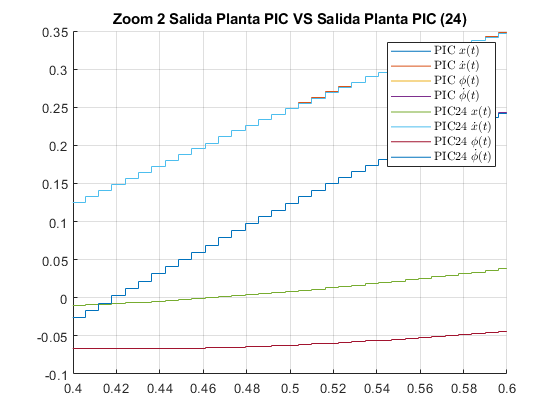


figure(10)
hold on
title('Zoom 2 Salida Planta PIC VS Salida Planta PIC (24)')
stairs(t,Y)
stairs(t,Y_24)
l=legend({'PIC $x(t)$','PIC $\dot{x}(t)$','PIC $\phi(t)$','PIC $\dot{\phi}(t)$','PIC24 $x(t)$','PIC24 $\dot{x}(t)$','PIC24 $\phi(t)$','PIC24 $\dot{\phi}(t)$'}); 
set(l,'interpreter','latex')
xlim([0.4 0.6])
grid on
hold off

Observador

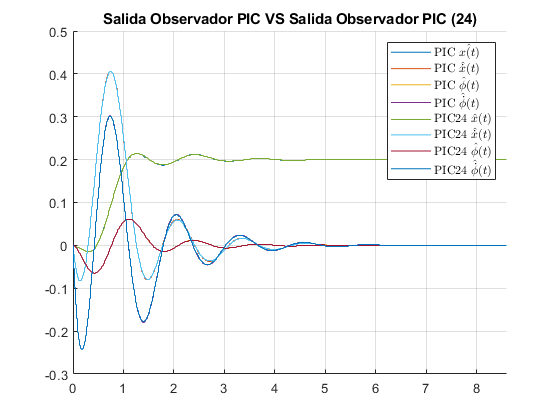

figure(11)
hold on
title('Salida Observador PIC VS Salida Observador PIC (24)')
stairs(t,Yo)
stairs(t,Yo_24)
l=legend({'PIC $\hat{x(t)}$','PIC $\hat{\dot{x}}(t)$','PIC $\hat{\phi}(t)$','PIC $\hat{\dot{\phi}}(t)$','PIC24 $\hat{x}(t)$','PIC24 $\hat{\dot{x}}(t)$','PIC24 $\hat{\phi}(t)$','PIC24 $\hat{\dot{\phi}}(t)$'}); 
set(l,'interpreter','latex')
xlim([0 t(end)])
grid on
hold off

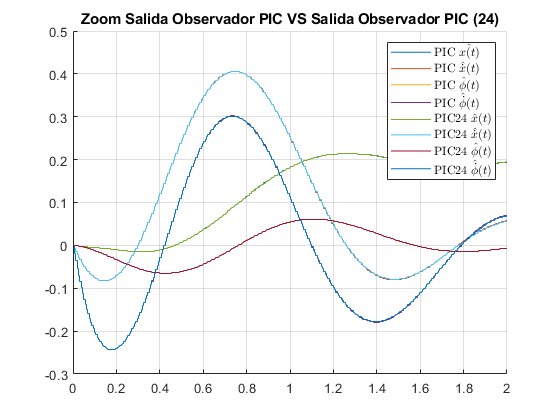


figure(12)
hold on
title('Zoom Salida Observador PIC VS Salida Observador PIC (24)')
stairs(t,Yo)
stairs(t,Yo_24)
l=legend({'PIC $\hat{x(t)}$','PIC $\hat{\dot{x}}(t)$','PIC $\hat{\phi}(t)$','PIC $\hat{\dot{\phi}}(t)$','PIC24 $\hat{x}(t)$','PIC24 $\hat{\dot{x}}(t)$','PIC24 $\hat{\phi}(t)$','PIC24 $\hat{\dot{\phi}}(t)$'}); 
set(l,'interpreter','latex')
xlim([0 2])
grid on
hold off

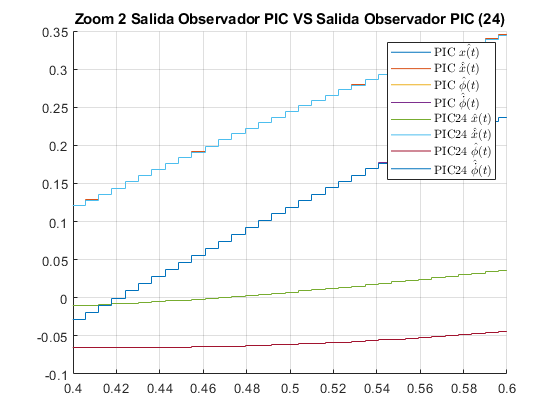


figure(13)
hold on
title('Zoom 2 Salida Observador PIC VS Salida Observador PIC (24)')
stairs(t,Yo)
stairs(t,Yo_24)
l=legend({'PIC $\hat{x(t)}$','PIC $\hat{\dot{x}}(t)$','PIC $\hat{\phi}(t)$','PIC $\hat{\dot{\phi}}(t)$','PIC24 $\hat{x}(t)$','PIC24 $\hat{\dot{x}}(t)$','PIC24 $\hat{\phi}(t)$','PIC24 $\hat{\dot{\phi}}(t)$'}); 
set(l,'interpreter','latex')
xlim([0.4 0.6])
grid on
hold off

***Errores***

Valor medio cuadratico entre el double de precision de 32 bits y el simulador 

errY_32_sim=immse(Y,Y_sim(2:end,:)')

errY_32_sim = 4.4988e-05

errYo_32_sim=immse(Yo,Yo_sim(2:end,:)')

errYo_32_sim = 4.4114e-05

Valor medio cuadratico entre el double de precision de 24 bits y el simulador 

errY_24_sim=immse(Y_24,Y_sim(2:end,:)')

errY_24_sim = 4.1791e-05

errYo_24_sim=immse(Yo_24,Yo_sim(2:end,:)')

errYo_24_sim = 4.1041e-05

Valor medio cuadratico entre el double de precision de 32 bits y el double de precision 24 bits

errY_32_24=immse(Y,Y_24)

errY_32_24 = 1.2120e-07

errYo_32_24=immse(Yo,Yo_24)

errYo_32_24 = 1.1457e-07